# Range-Velocity Matrix

clear; close all;

## 1. Построение сигнала

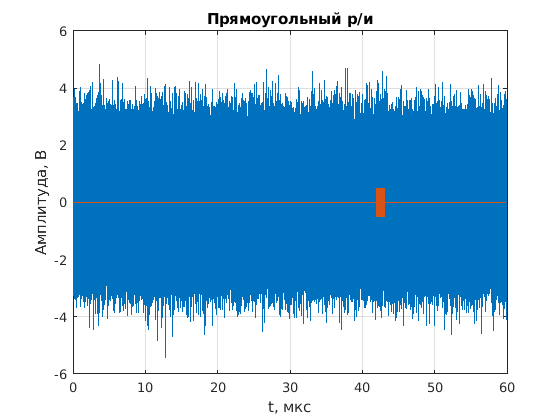

type_signal = "Прямоугольный р/и";
noise       = 0;
f0 = 3e9;       % несущая частота, Гц
fs = 10 * f0;   % частота дискретизации, Гц
dt = 1 / fs;    % период дискретизации, с
T  = 60e-6;     % время наблюдения (длительность строба), с
ti = 1e-6;      % длительность импульса, с
A  = 1;         % амплитуда сигнала, В
tz = 0.7;       % задержка сигнала относительно начала строба, -

t   = 0:dt:T-dt;    % вектор отсчетов времени строба, с
t_s = 0:dt:ti-dt;   % вектор отсчетов времени импульса, с

switch type_signal
    case "Прямоугольный р/и"
        s_op = A/2 * complex(cos(2*pi*f0*t_s), sin(2*pi*f0*t_s));
    case "ЛЧМ"
    case "ФКМ"
    otherwise
        error("Unknown signal type: %s", type_signal);
end

s = [zeros(1,fix(tz*T/dt)), s_op, zeros(1,length(t)-fix(tz*T/dt)-length(t_s))];
s_n = db2mag(noise)*complex(randn(1,length(t)), randn(1,length(t))) + s;

plot(t*1e6,real(s_n),t*1e6,real(s));
grid on; title(type_signal);
xlabel("t, мкс"); ylabel("Амплитуда, В");

## 2. Корреляционная обработка

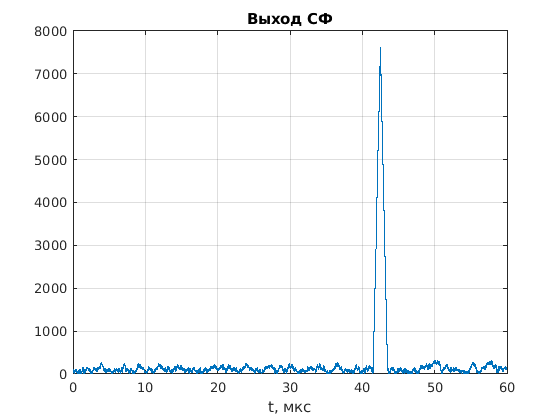

R = conv(s_n, conj(flip(s_op)), 'same');
plot(t*1e6,abs(R)); grid on;
xlabel("t, мкс"); title("Выход СФ");

[~,ind] = max(abs(R));
fprintf("Время прихода сигнала:\t%.2f мкс\n", (t(ind)-ti/2)*1e6);

Время прихода сигнала:	42.00 мкс
